# M E 325 Supplemental Homework 1

## TopHat Portion:

## Objective:

Reinforce the parameters that influence the fatigue life of a part and to determine the mean and alternating von Mises stresses for determination of a factor of safety using the Goodman and Langer failure envelopes.

### Determine:

- The theoretical stress concentration factor, $K_t$, using the link below

[https://efatigue-dev.altair.mediag.com](https://efatigue-dev.altair.mediag.com) 

- Notch sensitivity values, $q=\frac{1}{1+\frac{\sqrt{a}}{\sqrt{r}}}$

- Fatigue stress concentration factors, $K_f =q\left(K_t -1\right)+1$

- Adjusted stress values accounting for stress risers in geometry

- Mean and alternating von Mises stresses, $\sigma_m^{\prime } ,\sigma_a^{\prime }$

- Fatigue strength, $S_f$, at a specified number of stress cycles, $N$. $S_f =AN^b$

- Factor of safety against fatigue and yielding using the Goodman and Langer failure envelopes.

### Given Data:

$D=2\ldotp 0\textrm{in}$, $d=1\ldotp 75\textrm{in}$, $r=0\ldotp 25\textrm{in}$, $S_{\textrm{ut}} =90\textrm{kpsi}$, $S_y =75\textrm{kpsi}$

D = 2

D = 2

d = 1.75

d = 1.7500

r = 0.25

r = 0.2500

S_ultimate = 90

S_ultimate = 90

S_yield = 75

S_yield = 75

#### Question 1:

The round shaft shown below has a U-shpaed groove milled around its perimeter. The major diameter, $D$, is 2.0in, the minor diameter, $d$, is 1.75in, and the groove around the radius, $r$, of 0.25in. For the loadings shown, what is the theoretical stress concentration factor, $K_t$?

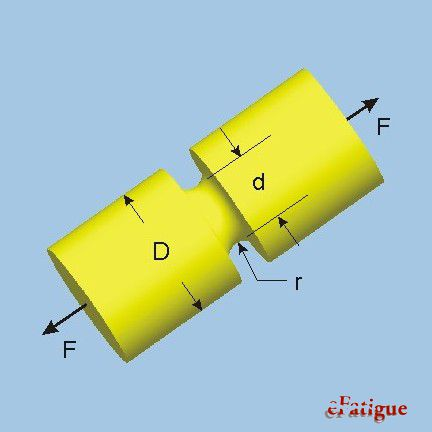

Utilizing the website linked in the problem statement:


$$K_t =1\ldotp 94$$


K_t_tension = 1.94

K_t_tension = 1.9400

An associated Peterson Plot has been added below showing the calculation:

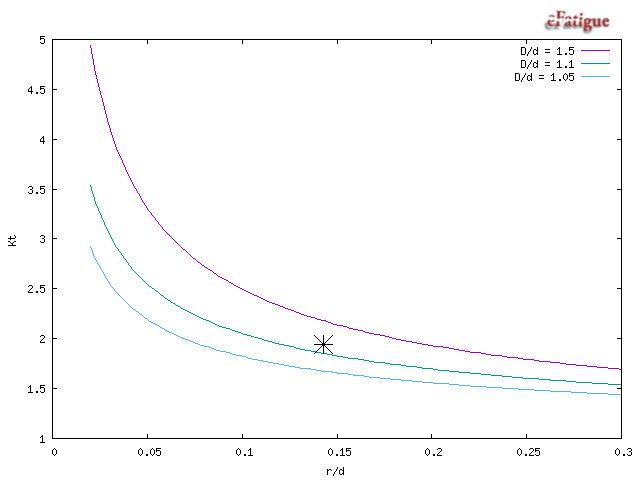

#### Question 2:

If the ultimate tensile strength for this component is 90 kpsi, what is the value of the fatigue stress concentration factor, $K_f$?

The fatigue stress concentration factor, $K_f$, is represented by


$$K_f =q\left(K_t -1\right)+1$$


where $q$ is the notch sensitivity and $K_t$ is the stress concentration factor. The notch sensitivity, $q$, is represented by


$$q=\frac{1}{1+\frac{\sqrt{a}}{\sqrt{r}}}$$


where $\sqrt{a}$ is the Neuber's constant and $r$ is the notch radius. In the case of tensile loading, the equation for Neuber's constant, $\sqrt{a}$, is the following:


$$\sqrt{a}=0\ldotp 246-3\ldotp 08\left({10}^{-3} \right)S_{\textrm{ut}} +1\ldotp 51\left({10}^{-5} \right)S_{\textrm{ut}}^2 -2\ldotp 67\left({10}^{-8} \right)S_{\textrm{ut}}^3$$


for $50\le S_{\textrm{ut}} \le 250\textrm{kpsi}$. 

Find Neuber's contstant, $\sqrt{a}$:

neuber_tension = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber_tension = 0.0716

We find Neuber's constant for this specimen to be $0\ldotp 0716\;{\textrm{in}}^{\frac{1}{2}}$.

Find notch sensitivity, $q$:

q_tension = 1/(1 + (neuber_tension/sqrt(r)))

q_tension = 0.8747

We find the notch sensitivity to be $0\ldotp 8747$.

Subbing in $q$:

K_f_tension = q_tension*(K_t_tension-1)+1

K_f_tension = 1.8222

We find the fatigue stress concentration factor to be $1\ldotp 8222$.

#### Question 3:

If the ultimate tensile strength for this component is 90kpsi, what is the value of the fatigue stress concentration factor, $K_f$, if the shaft is loaded as indicated in the accompanying picture?

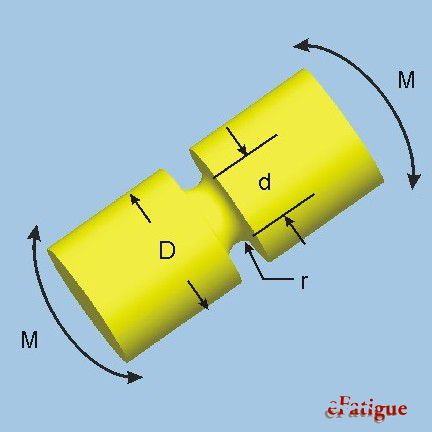

This specimen is loaded with a bending moment. As before, the stress concentration factor, $K_t$, is calculated from the eFatigue website. Inputing the data into the website, we find:


$$K_t =1\ldotp 7$$


K_t_bending = 1.7

K_t_bending = 1.7000

An associated Peterson Plot has been added below showing the calculation:

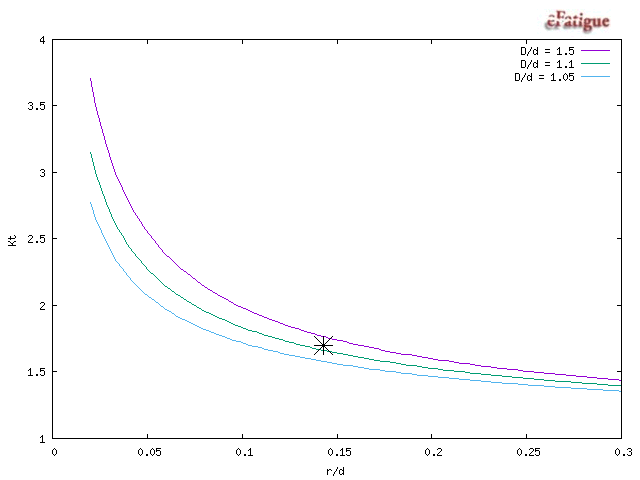

In the case of bending, we calculate Neuber's constant with the same equation as the last question

neuber_bending = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber_bending = 0.0716

The notch sensitivity is calculated in the same manner as well:

q_bending = 1/(1 + (neuber_bending/sqrt(r)))

q_bending = 0.8747

And finally, the fatigue stress concentration factor, $K_f$, is calculated:

K_f_bending = q_bending*(K_t_bending-1)+1

K_f_bending = 1.6123

#### Question 4

If the shaft is loaded as indicated below and $S_{\textrm{ut}\;} =90\textrm{kpsi}$, what is the value of the stress concentration value, $K_f$?

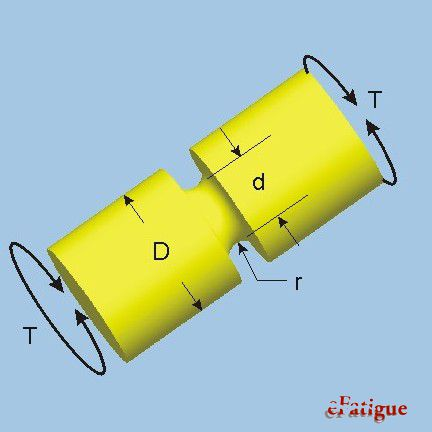

The specimen in this scenario has torsion applied to it. Once again the stress concentration factor is pulled from the website.


$$K_t =1\ldotp 35$$


K_t_torsion = 1.35

K_t_torsion = 1.3500

The Peterson Plot associatied with this calculation is shown below

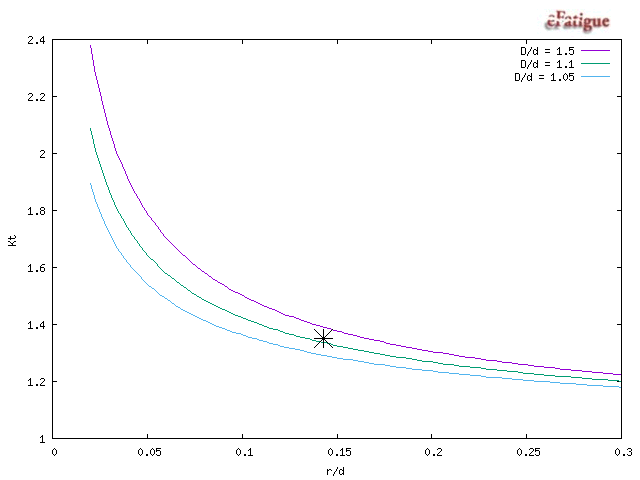

Since this specimen is in torsion, the neubers constant uses a different equation:

neuber_torsion = 0.190-2.51*(10^-3)*S_ultimate + 1.35*(10^-5)*S_ultimate^2 - 2.67*(10^-8)*S_ultimate^3

neuber_torsion = 0.0540

The notch sensitivity is calculated:

q_torsion = 1/(1 + (neuber_torsion/sqrt(r)))

q_torsion = 0.9026

And finally, the fatigue stress concentration factor, $K_f$, is calculated:

K_f_torsion = q_torsion*(K_t_torsion-1)+1

K_f_torsion = 1.3159

#### Question 5

If $F$ is applied such that a tensile stress occurs, and the value of $F$ is 1000lb, what is the adjusted stress, $\sigma_{\mathrm{x1}}$ in $\frac{\mathrm{lb}}{{\mathrm{in}}^2 }$?

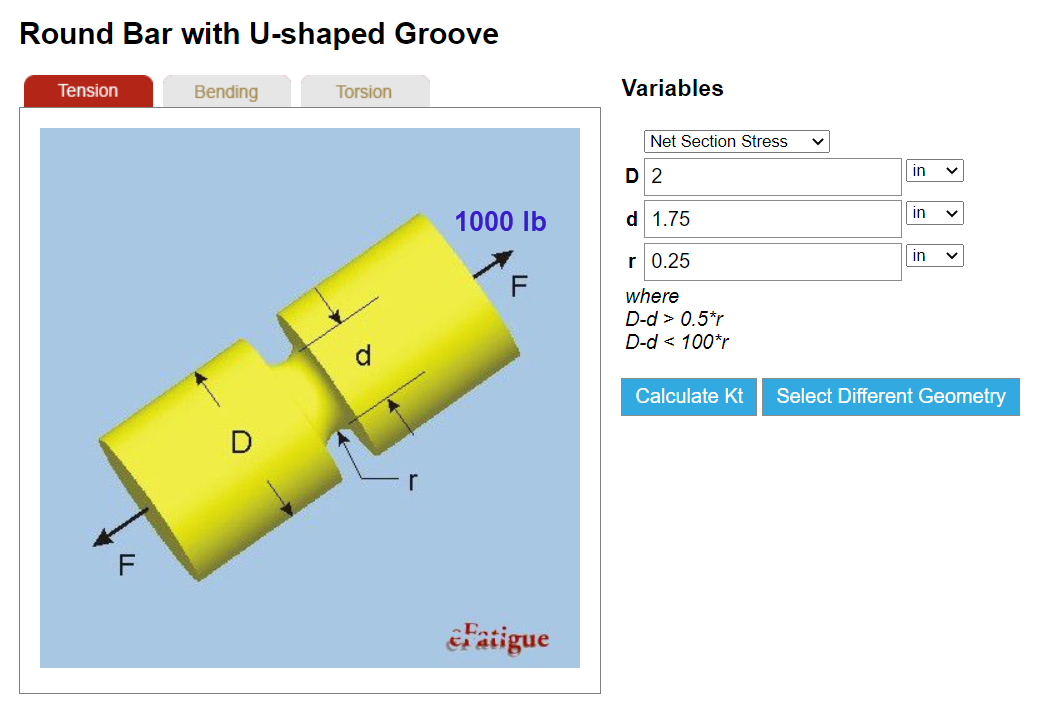

F_x = 1000

F_x = 1000

A = (pi*(d^2))/4

A = 2.4053

stress_x_1 = K_f_tension*(F_x/A)

stress_x_1 = 757.5776

#### Question 6

If $M$ is applied such that a tensile stress occurs, and the value of $M$ is 840lb-in, what is the adjusted stress, $\sigma_{\mathrm{x2}}$ in $\frac{\textrm{lb}}{{\textrm{in}}^2 }$?

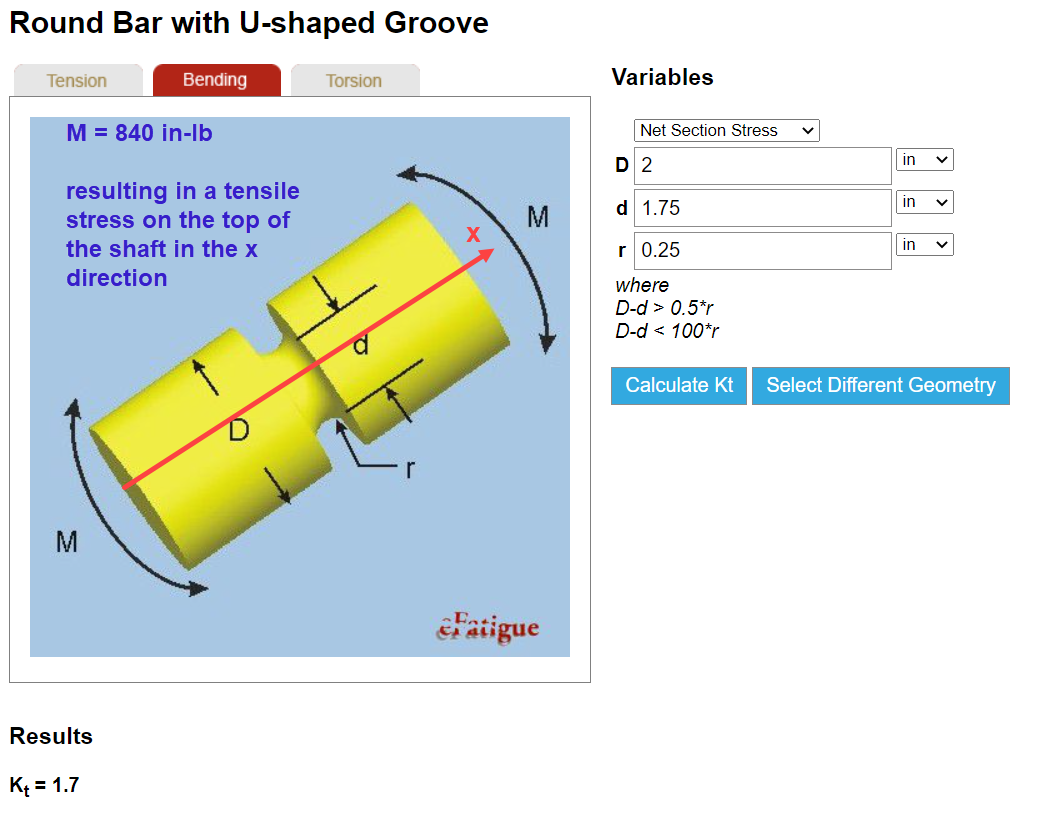

M_z = 840

M_z = 840

I = (pi*d^4)/64

I = 0.4604

stress_x_2 = K_f_bending * ((M_z * d/2)/I)

stress_x_2 = 2.5740e+03

#### Question 7

If $T$ is applied such that it is CW around the x-axis, and $T$ has a value of $400\;\mathrm{in}-\mathrm{lb}$, what is the adjusted value of the shear stress, ${K_f }_{\mathrm{torsion}} \tau_{\mathrm{xz}}$ in $\frac{\mathrm{lb}}{{\mathrm{in}}^2 }$?

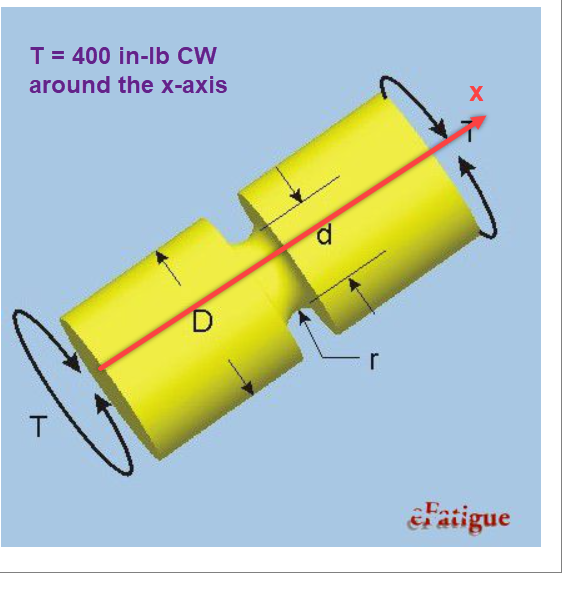

T_x = 400

T_x = 400

J = (pi*d^4)/32

J = 0.9208

shear_xz = (T_x*d/2)/J

shear_xz = 380.1158

stress_x_3 = K_f_torsion*shear_xz

stress_x_3 = 500.1916

#### Question 8

What is the total value of normal stress acting on the shaft in $\frac{\mathrm{lb}}{{\mathrm{in}}^2 }$?

normal_stress_total = stress_x_1 + stress_x_2

normal_stress_total = 3.3315e+03

## Code portion:

#### Calculate Marin Factors

Surface Factor, $k_a$:


$$k_a =aS_{\mathrm{ut}}^b$$


For machined surface, $a=2\ldotp 00$, $b=-0\ldotp 217$

a_surface = 2.00

a_surface = 2

b_surface = -0.217

b_surface = -0.2170

k_a = a_surface*S_ultimate^b_surface

k_a = 0.7533

Size Factor, $k_b$:


$$k_b ={\left(\frac{d}{0\ldotp 3}\right)}^{-0\ldotp 107} =0\ldotp 879d^{-0\ldotp 107}$$


k_b = 0.879*d^-0.107

k_b = 0.8279

Loading Factor, $k_c$:

For combined loading:


$$k_c =1$$


k_c = 1

k_c = 1

Temperature Factor, $k_d$:


$$k_d =S_T /S_{\mathrm{RT}} =0\ldotp 98+3\ldotp 5\left({10}^{-4} \right)T_F -6\ldotp 3\left({10}^{-7} \right)T_F^2$$


T_F = 600

T_F = 600

k_d = 0.98 + 3.5*(10^-4)*T_F - 6.3*(10^-7)*T_F^2

k_d = 0.9632

Reliability Factor, $k_e$:

With a reliability percentage of 99% (Table6-4):


$$k_e =0\ldotp 814$$


k_e = 0.814

k_e = 0.8140

Miscellaneous Factor, $k_f$:


$$k_f =1$$


k_f = 1

k_f = 1